## HCP Lockbox Sample - Whole-Brain Coupling Plot Across Conditions

Computation of coupling measure-specific brain-average coupling values for all eight conditions, taking the mean across the four measure-specific brain-average coupling values per condition and creating the violin plot visualizing condition-specific differences in brain-average SC-FC coupling. Run ANOVA to test for significant differences between brain-average condition-specific SC-FC coupling. 

Before running this script: 

- run all scripts in HCP Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:232
    whole_brain_values_HCP_rest{i,1} = mean(final_r_all_HCP_rest_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_rest{i,2} = mean(final_r_all_HCP_rest_232{i,1}(:,2));% G 
    whole_brain_values_HCP_rest{i,3} = mean(final_r_all_HCP_rest_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_rest{i,4} = mean(final_r_all_HCP_rest_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_rest_table = cell2table(whole_brain_values_HCP_rest);
 whole_brain_values_HCP_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_rest_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.31539      0.321    0.34476       0.26
    0.26291    0.27266    0.28374     0.2043
    0.28456    0.30044      0.322    0.22417
    0.27029    0.28931    0.30162    0.20643
    0.29058    0.31005    0.33726    0.25208
    0.29763     0.2951     0.3231    0.23832
    0.30297    0.32381    0.34303    0.24936
    0.28923    0.30706    0.32261    0.23144
    0.27254    0.28133    0.29559    0.21331
    0.30827    0.30247    0.33588    0.26683
    0.26635    0.27488     0.2961     0.2177
    0.27615    0.28755    0.30365    0.23868
    0.26643    0.27229    0.29075    0.22342
    0.27853    0.27321    0.29075    0.20749
    0.29969    0.32504     0.3481    0.26142
    0.29458    0.31232    0.33809    0.22867


1.2. Emotion processing (176 frames)

for i = 1:232
    whole_brain_values_HCP_emotion{i,1} = mean(final_r_all_HCP_emotion_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_emotion{i,2} = mean(final_r_all_HCP_emotion_232{i,1}(:,2));% G 
    whole_brain_values_HCP_emotion{i,3} = mean(final_r_all_HCP_emotion_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_emotion{i,4} = mean(final_r_all_HCP_emotion_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_emotion_table = cell2table(whole_brain_values_HCP_emotion);
 whole_brain_values_HCP_emotion_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_emotion_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19341    0.18565     0.1972    0.17178
    0.15446    0.15931    0.16371    0.12664
    0.18296      0.184    0.19467    0.13895
    0.14408    0.16264    0.16579    0.11483
     0.1818    0.18593    0.19497    0.14674
    0.18665    0.17516    0.19254     0.1654
    0.19386    0.19607    0.20595    0.16557
    0.16897    0.17656    0.17309    0.14467
    0.17056    0.18167    0.18765    0.13022
    0.17278    0.17497    0.17948    0.12649
    0.19438    0.19597    0.21399    0.16742
    0.14072    0.16433    0.16288    0.11543
    0.20384    0.21124    0.22627    0.18034
    0.17142    0.16327    0.17488    0.14408
    0.15739    0.18072    0.18358    0.13603
    0.16397     0.1879    0.18029    0.10512


1.3. Gambling (253 frames)

for i = 1:232
    whole_brain_values_HCP_gambling{i,1} = mean(final_r_all_HCP_gambling_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_gambling{i,2} = mean(final_r_all_HCP_gambling_232{i,1}(:,2));% G 
    whole_brain_values_HCP_gambling{i,3} = mean(final_r_all_HCP_gambling_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_gambling{i,4} = mean(final_r_all_HCP_gambling_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_gambling_table = cell2table(whole_brain_values_HCP_gambling);
 whole_brain_values_HCP_gambling_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_gambling_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24061    0.24362    0.25663    0.19622
    0.21102    0.23029    0.23516    0.15753
    0.22302    0.22628    0.24071    0.19053
    0.22523    0.24387    0.25512    0.18299
    0.21038    0.22639     0.2372     0.1637
    0.21779    0.22476    0.23471    0.17377
    0.23837    0.24622    0.26024    0.20608
    0.22416    0.22582    0.23312    0.18885
    0.24547     0.2333     0.2512    0.21051
    0.23346    0.23817    0.25879    0.20444
    0.20639    0.22741    0.23114    0.16543
    0.22299    0.23261    0.24194    0.20248
    0.23203    0.23822    0.24453    0.19734
    0.19154    0.20567    0.20682    0.13208
    0.21781    0.22718    0.23158    0.18946
    0.24083    0.27119    0.28253    0.20132


1.4. Language (316 frames)

for i = 1:232
    whole_brain_values_HCP_language{i,1} = mean(final_r_all_HCP_language_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_language{i,2} = mean(final_r_all_HCP_language_232{i,1}(:,2));% G 
    whole_brain_values_HCP_language{i,3} = mean(final_r_all_HCP_language_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_language{i,4} = mean(final_r_all_HCP_language_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_language_table = cell2table(whole_brain_values_HCP_language);
 whole_brain_values_HCP_language_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_language_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.26212    0.25965    0.27253    0.20718
    0.22025    0.24831    0.25517    0.17251
    0.22903     0.2443     0.2525    0.17539
    0.24844    0.26628    0.27567    0.18467
    0.23998     0.2475    0.26714    0.21006
    0.25878    0.25747    0.27834    0.20878
    0.22826    0.24914    0.25676    0.16527
    0.26475    0.26297    0.28178    0.20738
    0.22865    0.24708    0.25366    0.17944
    0.25122    0.25684    0.26531    0.19437
    0.24998    0.26393    0.28321    0.20555
    0.21594    0.24067     0.2483    0.17563
     0.2239    0.24505    0.24422    0.17273
    0.21345    0.23025    0.23372    0.15016
    0.23021    0.25355    0.26384    0.18687
    0.23983    0.26736    0.27459    0.17153


1.5. Motor (284 frames)

for i = 1:232
    whole_brain_values_HCP_motor{i,1} = mean(final_r_all_HCP_motor_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_motor{i,2} = mean(final_r_all_HCP_motor_232{i,1}(:,2));% G 
    whole_brain_values_HCP_motor{i,3} = mean(final_r_all_HCP_motor_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_motor{i,4} = mean(final_r_all_HCP_motor_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_motor_table = cell2table(whole_brain_values_HCP_motor);
 whole_brain_values_HCP_motor_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_motor_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.23134    0.22999    0.23974    0.19211
    0.22817    0.23197    0.24549    0.18474
    0.20848    0.21468    0.23065    0.19001
     0.1969    0.21324    0.22517    0.15116
    0.18138    0.19468     0.1964    0.14372
     0.2329    0.22201    0.24106    0.19401
    0.23052    0.22638     0.2387     0.1771
    0.22917    0.22603    0.23772    0.20426
    0.22215    0.22355    0.23228    0.17767
    0.23238    0.21787    0.23743    0.20436
     0.2157    0.21925    0.22687    0.17191
    0.21957    0.23035    0.24018    0.18245
    0.22468    0.24131    0.24741    0.17453
     0.2421     0.2273    0.25023    0.22211
    0.22646    0.23048    0.23756    0.18311
    0.22322    0.24753    0.25832    0.18062


1.6. Relational (232 frames)

for i = 1:232
    whole_brain_values_HCP_relational{i,1} = mean(final_r_all_HCP_relational_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_relational{i,2} = mean(final_r_all_HCP_relational_232{i,1}(:,2));% G 
    whole_brain_values_HCP_relational{i,3} = mean(final_r_all_HCP_relational_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_relational{i,4} = mean(final_r_all_HCP_relational_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_relational_table = cell2table(whole_brain_values_HCP_relational);
 whole_brain_values_HCP_relational_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_relational_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.23227     0.2393    0.25673    0.20515
    0.22249    0.23019    0.23671    0.18691
    0.20845    0.21666    0.22819    0.16495
    0.20344    0.22831    0.23467    0.16911
    0.17563    0.19246    0.20022    0.13039
    0.26589    0.25505    0.28165    0.22343
    0.20718    0.23074    0.23875    0.15927
    0.23417    0.23676    0.25008    0.20178
     0.2331    0.24109    0.25462    0.20267
    0.19494    0.19853     0.2037    0.15725
    0.23181    0.22705    0.24062    0.21175
    0.19282    0.20906    0.20699    0.15569
    0.22492    0.23733    0.24205    0.17459
    0.21714    0.22016    0.22971    0.17422
    0.19142    0.22063    0.22808    0.16391
    0.20515    0.23934    0.24199    0.13355

1.7. Social (274 frames)

for i = 1:232
    whole_brain_values_HCP_social{i,1} = mean(final_r_all_HCP_social_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_social{i,2} = mean(final_r_all_HCP_social_232{i,1}(:,2));% G 
    whole_brain_values_HCP_social{i,3} = mean(final_r_all_HCP_social_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_social{i,4} = mean(final_r_all_HCP_social_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_social_table = cell2table(whole_brain_values_HCP_social);
 whole_brain_values_HCP_social_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_social_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.23342    0.24316    0.25168    0.21221
    0.23271    0.24442    0.25169    0.20001
     0.2335    0.24374     0.2574    0.19429
    0.22577    0.25176    0.25777    0.18024
    0.20937    0.24301    0.24685    0.16806
    0.24605    0.25612    0.27039    0.19258
    0.27317    0.28128    0.29778    0.22282
    0.22849    0.24743    0.25438    0.19923
    0.23929    0.24901    0.25665    0.19089
    0.23951    0.24173    0.24899    0.18787
    0.21308    0.23198    0.24565     0.1744
    0.18254    0.21504    0.21285    0.15018
     0.2227    0.23912     0.2454      0.184
    0.21316    0.23296    0.23837    0.16599
    0.22536    0.25351    0.26271    0.18835
    0.25076    0.27942    0.28699    0.18152


1.8. WM (405 frames)

for i = 1:232
    whole_brain_values_HCP_wm{i,1} = mean(final_r_all_HCP_wm_232{i,1}(:,1));% Pl
    whole_brain_values_HCP_wm{i,2} = mean(final_r_all_HCP_wm_232{i,1}(:,2));% G 
    whole_brain_values_HCP_wm{i,3} = mean(final_r_all_HCP_wm_232{i,1}(:,3));% Cos
    whole_brain_values_HCP_wm{i,4} = mean(final_r_all_HCP_wm_232{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_wm_table = cell2table(whole_brain_values_HCP_wm);
 whole_brain_values_HCP_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_wm_table = 232×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.25185    0.26994    0.28064    0.21604
    0.21259    0.23108    0.23152    0.15967
    0.24703    0.26118    0.27525    0.19191
     0.2317    0.26029    0.26504    0.19052
    0.24039    0.25255    0.26145    0.20242
    0.24177    0.24807    0.26806    0.20029
    0.24412    0.26924    0.27758    0.19622
    0.27343     0.2771    0.28889    0.23238
    0.22147     0.2383    0.23788    0.17569
    0.25241    0.25748    0.26829    0.21189
    0.26319     0.2619      0.278    0.22304
    0.22996    0.24945    0.24736    0.18301
    0.23505    0.25229    0.25441    0.18999
    0.24978    0.24983    0.26589    0.19391
    0.20376    0.23066    0.22876    0.16465
    0.24456    0.28267    0.28346    0.19327


**2. Average coupling measures within the conditions**

2.1. Take average across all resting-state values 

Rest_values_from_all_measures = [whole_brain_values_HCP_rest_table.Pl whole_brain_values_HCP_rest_table.G whole_brain_values_HCP_rest_table.Cos whole_brain_values_HCP_rest_table.SI]

Rest_values_from_all_measures =     0.3154    0.3210    0.3448    0.2600
    0.2629    0.2727    0.2837    0.2043
    0.2846    0.3004    0.3220    0.2242
    0.2703    0.2893    0.3016    0.2064
    0.2906    0.3101    0.3373    0.2521
    0.2976    0.2951    0.3231    0.2383
    0.3030    0.3238    0.3430    0.2494
    0.2892    0.3071    0.3226    0.2314
    0.2725    0.2813    0.2956    0.2133
    0.3083    0.3025    0.3359    0.2668


Rest_all = mean(Rest_values_from_all_measures,2)

Rest_all =     0.3103
    0.2559
    0.2828
    0.2669
    0.2975
    0.2885
    0.3048
    0.2876
    0.2657
    0.3034


2.2. Take average across all emotion-processing values 

Emotion_values_from_all_measures = [whole_brain_values_HCP_emotion_table.Pl whole_brain_values_HCP_emotion_table.G whole_brain_values_HCP_emotion_table.Cos whole_brain_values_HCP_emotion_table.SI]

Emotion_values_from_all_measures =     0.1934    0.1857    0.1972    0.1718
    0.1545    0.1593    0.1637    0.1266
    0.1830    0.1840    0.1947    0.1390
    0.1441    0.1626    0.1658    0.1148
    0.1818    0.1859    0.1950    0.1467
    0.1867    0.1752    0.1925    0.1654
    0.1939    0.1961    0.2060    0.1656
    0.1690    0.1766    0.1731    0.1447
    0.1706    0.1817    0.1876    0.1302
    0.1728    0.1750    0.1795    0.1265


Emotion_all = mean(Emotion_values_from_all_measures,2)

Emotion_all =     0.1870
    0.1510
    0.1751
    0.1468
    0.1774
    0.1799
    0.1904
    0.1658
    0.1675
    0.1634


2.3. Take average across all gambling values 

Gambling_values_from_all_measures = [whole_brain_values_HCP_gambling_table.Pl whole_brain_values_HCP_gambling_table.G whole_brain_values_HCP_gambling_table.Cos whole_brain_values_HCP_gambling_table.SI]

Gambling_values_from_all_measures =     0.2406    0.2436    0.2566    0.1962
    0.2110    0.2303    0.2352    0.1575
    0.2230    0.2263    0.2407    0.1905
    0.2252    0.2439    0.2551    0.1830
    0.2104    0.2264    0.2372    0.1637
    0.2178    0.2248    0.2347    0.1738
    0.2384    0.2462    0.2602    0.2061
    0.2242    0.2258    0.2331    0.1889
    0.2455    0.2333    0.2512    0.2105
    0.2335    0.2382    0.2588    0.2044


Gambling_all = mean(Gambling_values_from_all_measures,2)

Gambling_all =     0.2343
    0.2085
    0.2201
    0.2268
    0.2094
    0.2128
    0.2377
    0.2180
    0.2351
    0.2337


2.4. Take average across all language values 

Language_values_from_all_measures = [whole_brain_values_HCP_language_table.Pl whole_brain_values_HCP_language_table.G whole_brain_values_HCP_language_table.Cos whole_brain_values_HCP_language_table.SI]

Language_values_from_all_measures =     0.2621    0.2597    0.2725    0.2072
    0.2203    0.2483    0.2552    0.1725
    0.2290    0.2443    0.2525    0.1754
    0.2484    0.2663    0.2757    0.1847
    0.2400    0.2475    0.2671    0.2101
    0.2588    0.2575    0.2783    0.2088
    0.2283    0.2491    0.2568    0.1653
    0.2648    0.2630    0.2818    0.2074
    0.2286    0.2471    0.2537    0.1794
    0.2512    0.2568    0.2653    0.1944


Language_all = mean(Language_values_from_all_measures,2)

Language_all =     0.2504
    0.2241
    0.2253
    0.2438
    0.2412
    0.2508
    0.2249
    0.2542
    0.2272
    0.2419


2.5. Take average across all motor values 

Motor_values_from_all_measures = [whole_brain_values_HCP_motor_table.Pl whole_brain_values_HCP_motor_table.G whole_brain_values_HCP_motor_table.Cos whole_brain_values_HCP_motor_table.SI]

Motor_values_from_all_measures =     0.2313    0.2300    0.2397    0.1921
    0.2282    0.2320    0.2455    0.1847
    0.2085    0.2147    0.2307    0.1900
    0.1969    0.2132    0.2252    0.1512
    0.1814    0.1947    0.1964    0.1437
    0.2329    0.2220    0.2411    0.1940
    0.2305    0.2264    0.2387    0.1771
    0.2292    0.2260    0.2377    0.2043
    0.2221    0.2235    0.2323    0.1777
    0.2324    0.2179    0.2374    0.2044


Motor_all = mean(Motor_values_from_all_measures,2)

Motor_all =     0.2233
    0.2226
    0.2110
    0.1966
    0.1790
    0.2225
    0.2182
    0.2243
    0.2139
    0.2230


2.6. Take average across all relational values 

Relational_values_from_all_measures = [whole_brain_values_HCP_relational_table.Pl whole_brain_values_HCP_relational_table.G whole_brain_values_HCP_relational_table.Cos whole_brain_values_HCP_relational_table.SI]

Relational_values_from_all_measures =     0.2323    0.2393    0.2567    0.2052
    0.2225    0.2302    0.2367    0.1869
    0.2085    0.2167    0.2282    0.1649
    0.2034    0.2283    0.2347    0.1691
    0.1756    0.1925    0.2002    0.1304
    0.2659    0.2550    0.2816    0.2234
    0.2072    0.2307    0.2387    0.1593
    0.2342    0.2368    0.2501    0.2018
    0.2331    0.2411    0.2546    0.2027
    0.1949    0.1985    0.2037    0.1573


Relational_all = mean(Relational_values_from_all_measures,2)

Relational_all =     0.2334
    0.2191
    0.2046
    0.2089
    0.1747
    0.2565
    0.2090
    0.2307
    0.2329
    0.1886


2.7. Take average across all social values 

Social_values_from_all_measures = [whole_brain_values_HCP_social_table.Pl whole_brain_values_HCP_social_table.G whole_brain_values_HCP_social_table.Cos whole_brain_values_HCP_social_table.SI]

Social_values_from_all_measures =     0.2334    0.2432    0.2517    0.2122
    0.2327    0.2444    0.2517    0.2000
    0.2335    0.2437    0.2574    0.1943
    0.2258    0.2518    0.2578    0.1802
    0.2094    0.2430    0.2469    0.1681
    0.2460    0.2561    0.2704    0.1926
    0.2732    0.2813    0.2978    0.2228
    0.2285    0.2474    0.2544    0.1992
    0.2393    0.2490    0.2566    0.1909
    0.2395    0.2417    0.2490    0.1879


Social_all = mean(Social_values_from_all_measures,2)

Social_all =     0.2351
    0.2322
    0.2322
    0.2289
    0.2168
    0.2413
    0.2688
    0.2324
    0.2340
    0.2295


2.8. Take average across all wm values 

Wm_values_from_all_measures = [whole_brain_values_HCP_wm_table.Pl whole_brain_values_HCP_wm_table.G whole_brain_values_HCP_wm_table.Cos whole_brain_values_HCP_wm_table.SI]

Wm_values_from_all_measures =     0.2519    0.2699    0.2806    0.2160
    0.2126    0.2311    0.2315    0.1597
    0.2470    0.2612    0.2753    0.1919
    0.2317    0.2603    0.2650    0.1905
    0.2404    0.2525    0.2614    0.2024
    0.2418    0.2481    0.2681    0.2003
    0.2441    0.2692    0.2776    0.1962
    0.2734    0.2771    0.2889    0.2324
    0.2215    0.2383    0.2379    0.1757
    0.2524    0.2575    0.2683    0.2119


Wm_all = mean(Wm_values_from_all_measures,2)

Wm_all =     0.2546
    0.2087
    0.2438
    0.2369
    0.2392
    0.2395
    0.2468
    0.2679
    0.2183
    0.2475


**3. Create the violin plot**

3.1. Put all values into one table

Mean_values_conditions = [Rest_all Emotion_all Gambling_all Language_all Motor_all Relational_all Social_all Wm_all]

Mean_values_conditions =     0.3103    0.1870    0.2343    0.2504    0.2233    0.2334    0.2351    0.2546
    0.2559    0.1510    0.2085    0.2241    0.2226    0.2191    0.2322    0.2087
    0.2828    0.1751    0.2201    0.2253    0.2110    0.2046    0.2322    0.2438
    0.2669    0.1468    0.2268    0.2438    0.1966    0.2089    0.2289    0.2369
    0.2975    0.1774    0.2094    0.2412    0.1790    0.1747    0.2168    0.2392
    0.2885    0.1799    0.2128    0.2508    0.2225    0.2565    0.2413    0.2395
    0.3048    0.1904    0.2377    0.2249    0.2182    0.2090    0.2688    0.2468
    0.2876    0.1658    0.2180    0.2542    0.2243    0.2307    0.2324    0.2679
    0.2657    0.1675    0.2351    0.2272    0.2139    0.2329    0.2340    0.2183
    0.3034    0.1634    0.2337    0.2419    0.2230    0.1886    0.2295    0.2475


% Mean_values_conditions_cell = num2cell(Mean_values_conditions)
% Mean_values_conditions_table = cell2table(Mean_values_conditions_cell)
% Mean_values_conditions_table.Properties.VariableNames = {'Rest', 'Emotion', 'Gambling', 'Language', 'Motor', 'Relational', 'Social', 'Working Memory'}

3.2. Create violin plots 

% violinplot(Mean_values_conditions)
% ylabel('Brain-average Coupling (r)')
% xlabel('Condition')
% set(gca,'FontSize',15)
% ylim([0.05 0.4])

**4. Run ANOVAs **

Mean_values_conditions

Mean_values_conditions =     0.3103    0.1870    0.2343    0.2504    0.2233    0.2334    0.2351    0.2546
    0.2559    0.1510    0.2085    0.2241    0.2226    0.2191    0.2322    0.2087
    0.2828    0.1751    0.2201    0.2253    0.2110    0.2046    0.2322    0.2438
    0.2669    0.1468    0.2268    0.2438    0.1966    0.2089    0.2289    0.2369
    0.2975    0.1774    0.2094    0.2412    0.1790    0.1747    0.2168    0.2392
    0.2885    0.1799    0.2128    0.2508    0.2225    0.2565    0.2413    0.2395
    0.3048    0.1904    0.2377    0.2249    0.2182    0.2090    0.2688    0.2468
    0.2876    0.1658    0.2180    0.2542    0.2243    0.2307    0.2324    0.2679
    0.2657    0.1675    0.2351    0.2272    0.2139    0.2329    0.2340    0.2183
    0.3034    0.1634    0.2337    0.2419    0.2230    0.1886    0.2295    0.2475


groupnames = {'rest','emotion','gambling','language','motor','relational','social', 'wm'}

groupnames = 1×8 cell array
    {'rest'}    {'emotion'}    {'gambling'}    {'language'}    {'motor'}    {'relational'}    {'social'}    {'wm'}


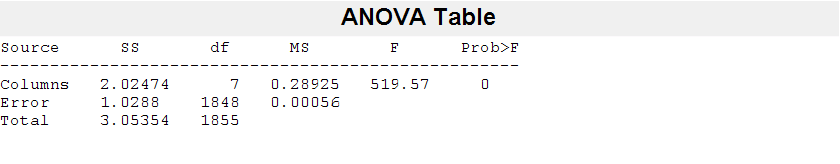

p = 0

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df'  }    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[2.0247]}    {[   7]}    {[    0.2892]}    {[519.5672]}    {[       0]}
    {'Error'  }    {[1.0288]}    {[1848]}    {[5.5671e-04]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[3.0535]}    {[1855]}    {0×0 double  }    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {8×1 cell}
         n: [232 232 232 232 232 232 232 232]
    source: 'anova1'
     means: [0.2919 0.1667 0.2159 0.2457 0.2178 0.2130 0.2314 0.2378]
        df: 1848
         s: 0.0236


[p,tbl,stats] = anova1(Mean_values_conditions,groupnames)

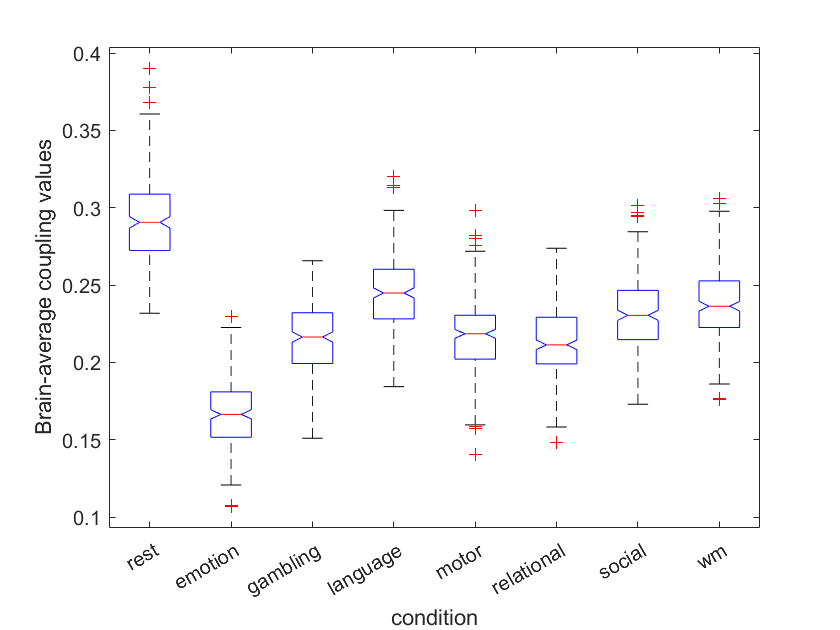

xlabel('condition')
ylabel('Brain-average coupling values')

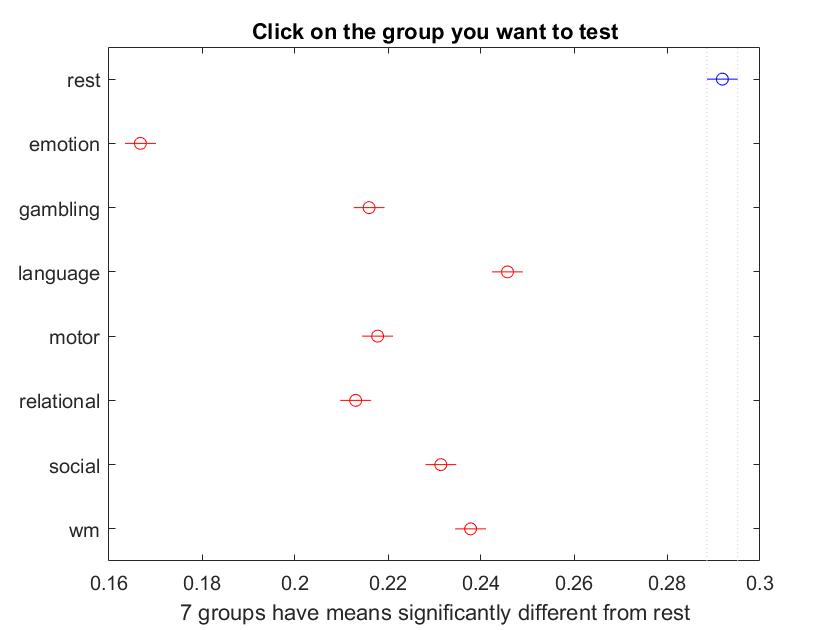

c =     1.0000    2.0000    0.1185    0.1252    0.1318         0
    1.0000    3.0000    0.0693    0.0760    0.0826         0
    1.0000    4.0000    0.0396    0.0462    0.0528         0
    1.0000    5.0000    0.0675    0.0741    0.0808         0
    1.0000    6.0000    0.0722    0.0789    0.0855         0
    1.0000    7.0000    0.0539    0.0605    0.0672         0
    1.0000    8.0000    0.0475    0.0541    0.0608         0
    2.0000    3.0000   -0.0558   -0.0492   -0.0425         0
    2.0000    4.0000   -0.0856   -0.0789   -0.0723         0
    2.0000    5.0000   -0.0577   -0.0510   -0.0444         0


gnames = 8×1 cell array
    {'rest'      }
    {'emotion'   }
    {'gambling'  }
    {'language'  }
    {'motor'     }
    {'relational'}
    {'social'    }
    {'wm'        }


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 28×6 table
    Group A    Group B    Lower Limit       A-B       Upper Limit    P-value
    _______    _______    ___________    _________    ___________    _______

       1          2          0.11851       0.12515       0.13179           0
       1          3         0.069327      0.075967      0.082607           0
       1          4         0.039565      0.046205      0.052845           0
       1          5         0.067496      0.074136      0.080776           0
       1          6         0.072222      0.078862      0.085501           0
       1          7         0.053906      0.060546      0.067186           0
       1          8           0.0475      0.054139      0.060779           0
       2          3        -0.055827     -0.049187     -0.042547           0
      

**5. Run Repeated-measures ANOVA **

data = Mean_values_conditions

data =     0.3103    0.1870    0.2343    0.2504    0.2233    0.2334    0.2351    0.2546
    0.2559    0.1510    0.2085    0.2241    0.2226    0.2191    0.2322    0.2087
    0.2828    0.1751    0.2201    0.2253    0.2110    0.2046    0.2322    0.2438
    0.2669    0.1468    0.2268    0.2438    0.1966    0.2089    0.2289    0.2369
    0.2975    0.1774    0.2094    0.2412    0.1790    0.1747    0.2168    0.2392
    0.2885    0.1799    0.2128    0.2508    0.2225    0.2565    0.2413    0.2395
    0.3048    0.1904    0.2377    0.2249    0.2182    0.2090    0.2688    0.2468
    0.2876    0.1658    0.2180    0.2542    0.2243    0.2307    0.2324    0.2679
    0.2657    0.1675    0.2351    0.2272    0.2139    0.2329    0.2340    0.2183
    0.3034    0.1634    0.2337    0.2419    0.2230    0.1886    0.2295    0.2475


subjects = (1:size(data,1))';  % Subject IDs

% Convert to table format
T = array2table(data, 'VariableNames', {'rest','emotion','gambling','language','motor','relational','social', 'wm'});
T.Subjects = subjects;

% Define Table
numbers = [1; 2; 3; 4; 5; 6; 7; 8]

numbers =      1
     2
     3
     4
     5
     6
     7
     8


Infotable = array2table(numbers, 'VariableNames', {'Condition'})

Infotable = 8×1 table
    Condition
    _________

        1    
        2    
        3    
        4    
        5    
        6    
        7    
        8    



% Define the repeated-measures model
rm = fitrm(T, 'rest-wm ~ 1', 'WithinDesign', Infotable);

% Perform repeated-measures ANOVA
ranovatbl = ranova(rm)

ranovatbl = 2×8 table
                              SumSq      DF       MeanSq        F       pValue    pValueGG    pValueHF     pValueLB 
                             _______    ____    __________    ______    ______    ________    ________    __________

    (Intercept):Condition     2.0247       7       0.28925    935.55       0          0           0       3.4441e-83
    Error(Condition)         0.49994    1617    0.00030918                                                          



% Display results
disp(ranovatbl)

                              SumSq      DF       MeanSq        F       pValue    pValueGG    pValueHF     pValueLB 
                             _______    ____    __________    ______    ______    ________    ________    __________

    (Intercept):Condition     2.0247       7       0.28925    935.55       0          0           0       3.4441e-83
    Error(Condition)         0.49994    1617    0.00030918                                                          



% Perform post-hoc tests
multcompare(rm, 'Condition')

ans = 56×7 table
    Condition_1    Condition_2    Difference     StdErr        pValue        Lower        Upper  
    ___________    ___________    __________    _________    __________    _________    _________

         1              2           0.12515     0.0020102    5.9881e-08      0.11906      0.13125
         1              3          0.075967     0.0019637    5.9881e-08     0.070015     0.081919
         1              4          0.046205      0.002017    5.9881e-08     0.040092     0.052318
         1              5          0.074136     0.0019842    5.9881e-08     0.068122      0.08015
         1              6          0.078862     0.0020691    5.9881e-08     0.072591     0.085133
         1              7          0.060546     0.0018098 